**e) The function getImageDescriptor gives the spatial histogram of the image. **

**What is the spatial histogram? **

It is a step of the object recognition by  Bag-of-Words algorithm done between the training visual words step and computing the feature kernel map. It consists of breaking the image down in cells and perform the histogram of visual words in each cell. Afterwards, the histograms of each cell are concatenated. This is done in order to keep spatial information which would have been lost if athe histogram is applied to the entire image only.

**What dimension does it have? **

The dimension of the histogram are the number of row cells times the number of columns cells (total number of partitions) times the number of visual words considered (bins). The "TinyProblem" settings of the code which considers only just 5 classes, have a 2 by 2 divisions (4 cells in total) with a total number of words value of 300. The size of the concatenated histogram sum up to 1200 values.  

**What happens if we augment model.numSpatialX from 2 to 4?**

First, the number of cells doubled together with the datapoints required in the histogram (2400). Secondly, the accuracy also increased from 92% to 96%. However, if model.numSpatialY is also set to 4, the number of histogram values increases to 4800 and the the average accuracy also improves up to 97.33%. Latest settings, all faces were correctly classified and the background images missclassified were reduced to 2.

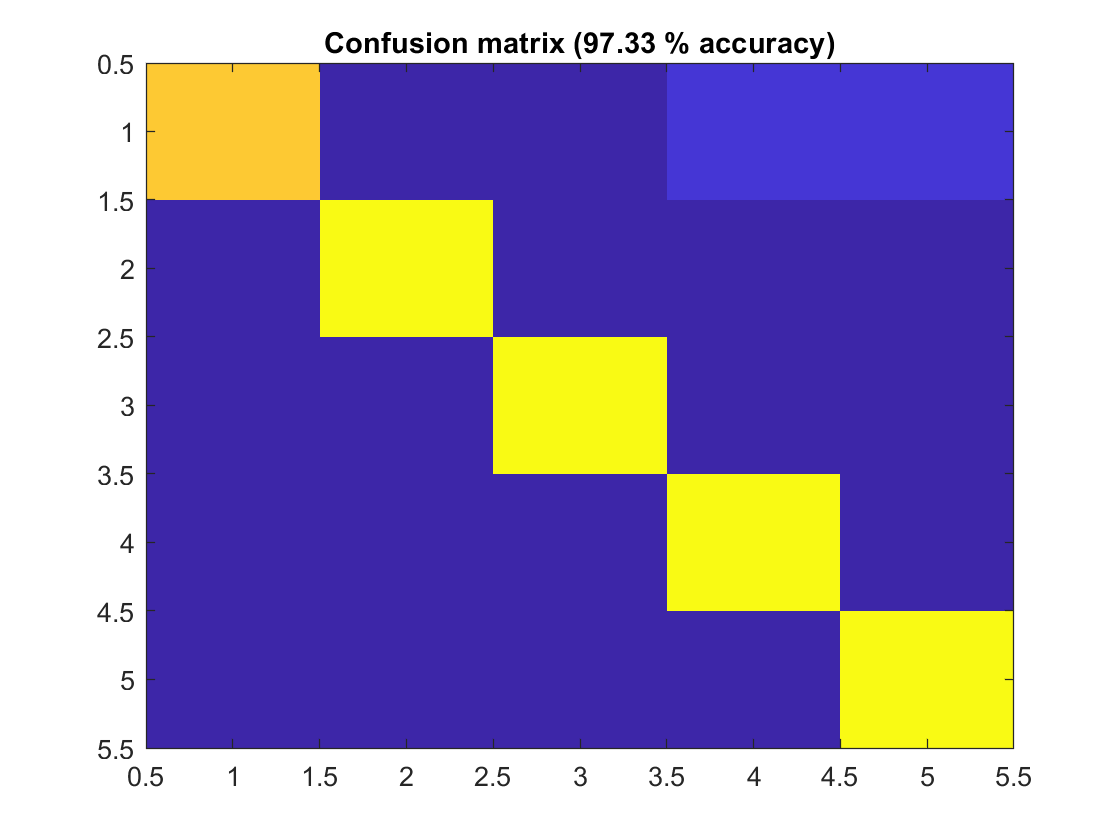

imagesc([13 0 0 1 1; 0 15 0 0 0; 0 0 15 0 0; 0 0 0 15 0; 0 0 0 0 15]);
title(sprintf('Confusion matrix (%.2f %% accuracy)', 97.33)) ;

**f) The SVM classification with homogeneous kernels is performed by the vl_svmtrain function that needs the homogeneous kernel map obtained by the vl_homkermap function. **

**What are the parameters obtained after the training process?**

The training process using SVM generates two main paramters named `W` (weights) and `b` (bias) which are persisted in the model object.

**What dimension do they have? **

A SVM model is trained for each class. 

The dimension of the weights of a single SVM model is the number of datapoints times the number of classes (1). With default settings of TinyProblem, the dimensions are 3600 x 1. The final W dimension of the training process will be the concatention of the weights for each class, with default settings, 5 classes (3600 x 5). The vector has a dimension of 3600 because the vl_homkermap computes a 2*N+1 dimensional approximated kernel map for the Chi2 kernel. The input vector of vl_homkermap is 1200 (the spatial histogram explained in e) and the value of N is 1. Thus 2*1+1 is 3, the output of the kernel map is 3 * 1200 = 3600 which is then passed to the SVM.

The dimension of the bias of a single SVM model is 1. Thus the final b dimension of the training process will be 1 x 5 (number of classes).

**How do you apply them to obtain the score of the final classification?**

The scores can be computed using the weights and the bias with the formula: $W^T X+b=Y$ and the sign of Y should match the Label or class vector made of -1 and +1 values.

g) Is the algorithm invariant to rotation of the images? 

Is the algorithm invariant to rescaling of the images?